# Week 12 In Class Assignment

clear, clc, close all;

## Prompt

You are managing a fleet of robots used in a manufacturing factory. Each robot performs routine tasks, which gradually wear down its components over time. Your goal is to simulate this wear and tear and monitor which robots require maintenance based on operational data.

Each **robot** has the following attributes:

- **ID**: A unique identifier for the robot

- **Component Life**: A structure with each component’s remaining life percentage (`motors`, `sensors`, `arms`, `battery`) initially set at 100%

- **Battery Efficiency**: Indicates how well each robot conserves power; a value between 0.5 and 1.5 (where lower values mean higher efficiency)

- **Usage Hours**: Total hours of operation since the last maintenance check

You will write a MATLAB function that simulates a week’s operation in the factory, decrementing the component life based on usage and efficiency, with conditional checks for maintenance requirements.

## Instructions

**1. Define a Structure Array**: Create a structure array with data for at least five robots, each initialized with 100% component life, a unique `ID`, a battery efficiency value, and zero `Usage Hours`.

**2.Create a Function **`simulateWorkWeek(robots, hoursPerDay, days)`:

- **Inputs**:

- `robots`: Structure array of robots

- `hoursPerDay`: Number of hours each robot operates daily

- `days`: Number of days to simulate (e.g., a week would be 7 days)

- **Behavior**:

- For each robot, update `Usage Hours` by adding the daily hours over the specified days.

- Reduce each component’s life based on `Usage Hours` and `Battery Efficiency`. For example:

- Motors and arms degrade by 1% for every 10 hours of operation.

- Sensors degrade by 0.5% every 10 hours.

- Battery efficiency affects degradation rate: more efficient batteries slow the component wear by a factor of `(2 - Efficiency)`.

- If any component life falls below 20%, flag the robot as needing maintenance.

- Add a probability of unexpected downtime if any component life is below 30%. Track downtime incidents for each robot in a field called `DowntimeHours`.

- **Outputs**: 

- The function returns the updated structure array and a list of `robot IDs` flagged for maintenance.

- Think about a way to visualize downtime per each robotID. 

- Think about any other potentially interesting visuals. 

**3. Report the Results**:

- Display each robot’s remaining component life and `Usage Hours` at the end of the simulation.

- Display the `robot IDs` of those flagged for maintenance.

robots = struct( ...
    'ID', {'R1', 'R2', 'R3', 'R4', 'R5'}, ...
    'ComponentLife', struct('motors', 100, 'sensors', 100, 'arms', 100, 'battery', 100), ...
    'BatteryEfficiency', {0.8, 1.1, 0.9, 0.7, 0.9}, ...
    'UsageHours', {0, 0, 0, 0, 0}, ...
    'DowntimeHours', {0, 0, 0, 0, 0} ...
);

hoursPerDay = 8;
days = 77;

[updatedRobots, maintenanceList] = simulateWorkWeek(robots, hoursPerDay, days);

for i = 1:length(updatedRobots)
    if (i == 1)
        disp('Robots: Week Operation')
        fprintf('#\tID\tUsage (hrs)\tDowntime (hrs)\tMotors (%%)\tSensors (%%)\tArms (%%)');
    end
    fprintf('%i\t%s\t%i\t\t%i\t\t%.1f\t\t%.1f\t\t%.1f\n', i, updatedRobots(i).ID, updatedRobots(i).UsageHours, updatedRobots(i).DowntimeHours, updatedRobots(i).ComponentLife.motors, updatedRobots(i).ComponentLife.sensors, updatedRobots(i).ComponentLife.arms)
    if (i == length(updatedRobots) && length(maintenanceList) ~= 0)
        disp(' ')
        disp('Robots: Required Maintenance Check')
        for j = 1:length(maintenanceList)
            fprintf('%s\n', maintenanceList{j})
        end
    end
end

Robots: Week Operation


#	ID	Usage (hrs)	Downtime (hrs)	Motors (%)	Sensors (%)	Arms (%)

1	R1	616		0		26.1		63.0		26.1
2	R2	616		0		44.6		72.3		44.6
3	R3	616		0		32.2		66.1		32.2
4	R4	329		287		19.9		60.0		19.9
5	R5	616		0		32.2		66.1		32.2


Robots: Required Maintenance Check


R4


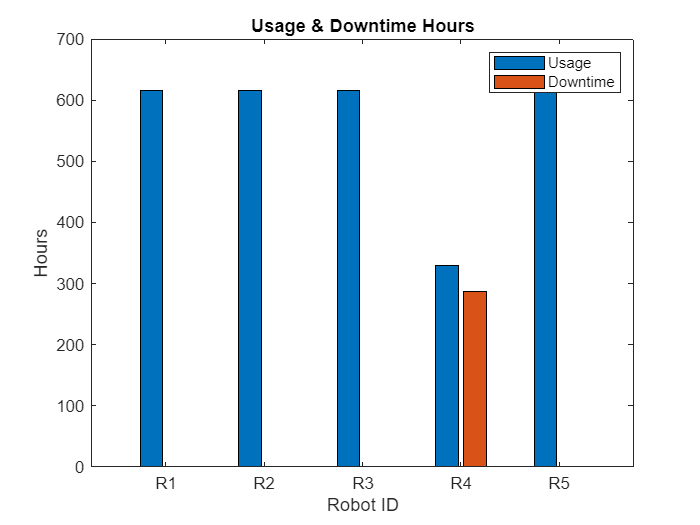

IDs = {updatedRobots.ID};
UsageHours = [updatedRobots.UsageHours];
DowntimeHours = [updatedRobots.DowntimeHours];
bar(IDs, [UsageHours; DowntimeHours]);
title("Usage & Downtime Hours");
xlabel("Robot ID");
ylabel("Hours");
legend("Usage", 'Downtime');

## Functions

function [updatedRobots, maintenanceList] = simulateWorkWeek(robots, hoursPerDay, days)
    updatedRobots = [];
    maintenanceList = [];
    
    for i = 1:length(robots)
        % Update usage hours.
        robots(i).UsageHours = robots(i).UsageHours + hoursPerDay * days;

        % Battery Efficiency
        Efficiency = 2 - robots(i).BatteryEfficiency;
        
        % Reduce component life.
        robots(i).ComponentLife.motors = robots(i).ComponentLife.motors - (hoursPerDay * days / 10) * Efficiency;
        robots(i).ComponentLife.sensors = robots(i).ComponentLife.sensors - (hoursPerDay * days / 20) * Efficiency;
        robots(i).ComponentLife.arms = robots(i).ComponentLife.arms - (hoursPerDay * days / 10) * Efficiency;

        % Get the numeric values of component life into an array.
        ComponentLife = structfun(@(x) x, robots(i).ComponentLife);
    
        % Flag for maintenance.
        if (ComponentLife(ComponentLife < 20))
            maintenanceList = [maintenanceList, {robots(i).ID}];
        end
    
        % Calculate downtime hours.
        if (ComponentLife(ComponentLife < 30))
            if (randi(10) <= 5)
                robots(i).DowntimeHours = robots(i).DowntimeHours + randi(hoursPerDay * days / 2);
                robots(i).UsageHours = robots(i).UsageHours - robots(i).DowntimeHours;
                if ~ismember(robots(i).ID, maintenanceList)
                    maintenanceList = [maintenanceList; {robots(i).ID}];
                end
            end
        end

        % Add to updatedRobots.
        updatedRobots = [updatedRobots, robots(i)];        
    end
end